%% Part 3 – Naive Bermudan Quadrature (no T–h smoothing)
clear; clc; tic;

function price = bermudan_quad_naive(S0,K,r,q,sigma,T,n_steps,m_grid)
    % ----- Time step and log-price grid -----
    h   = T / n_steps;                % adaptive daily step
    s0  = log(S0);
    smin = s0 - 10*sigma*sqrt(T);
    smax = s0 + 10*sigma*sqrt(T);
    s    = linspace(smin,smax,m_grid)'; 
    S    = exp(s);
    mid  = ceil(m_grid/2);
    ds   = s(2) - s(1);

    % ----- Conditional density matrix F(s_j | s_i) -----
    mu_shift = (r - q - 0.5*sigma^2)*h;
    sig_h    = sigma*sqrt(h);
    F = zeros(m_grid);
    for i = 1:m_grid
        mu_i = s(i) + mu_shift;
        z = (s' - mu_i)/sig_h;
        F(i,:) = (1/(sig_h*sqrt(2*pi))) * exp(-0.5*z.^2);
    end

    % ----- Simpson weights -----
    w = ones(m_grid,1);
    w(2:2:end-1)=4; w(3:2:end-2)=2;
    w = w*(ds/3);

    % ----- Terminal payoff -----
    v_next = max(K - S, 0);
    disc   = exp(-r*h);

    % ----- Backward recursion -----
    for t = 1:n_steps
        cont = disc * (F * (v_next .* w));
        v = max(K - S, cont);
        v_next = v;
    end

    price = v_next(mid);
end

% ===== Run test =====
S0=50; K=50; r=0.05; q=0.02; sigma=0.30;
T=60/365; n_steps=60; m_grid=401;
price = bermudan_quad_naive(S0,K,r,q,sigma,T,n_steps,m_grid);
fprintf('Naive Bermudan (no smoothing): %.6f\n',price);

Naive Bermudan (no smoothing): 2.308281


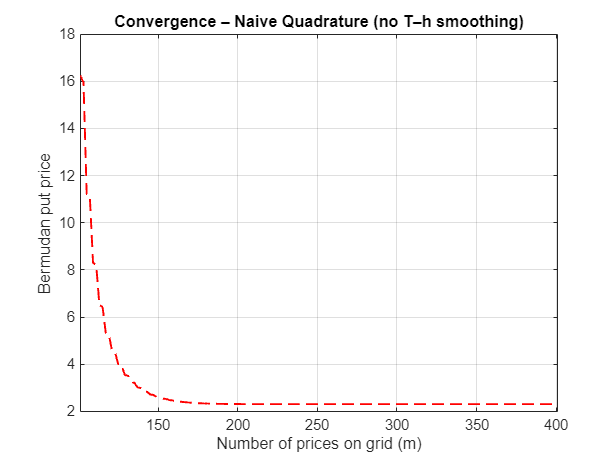


% ===== Convergence sweep =====
m_list = 101:2:m_grid;
prices = nan(size(m_list));
for k = 1:numel(m_list)
    prices(k) = bermudan_quad_naive(S0,K,r,q,sigma,T,n_steps,m_list(k));
end

% ===== Plot =====
figure; hold on; box on;
plot(m_list, prices,'r--','LineWidth',1.3);
xlabel('Number of prices on grid (m)');
ylabel('Bermudan put price');
title('Convergence – Naive Quadrature (no T–h smoothing)');
grid on; xlim([min(m_list) max(m_list)]);

toc;

Elapsed time is 0.983498 seconds.


%% Part 4 – Bermudan Quadrature with T–h smoothing
clear; clc; tic;

function price = bermudan_quad_smooth(S0,K,r,q,sigma,T,n_steps,m_grid)
    % ----- Time step and grid -----
    h   = T / n_steps;              % step size (should be 1/365 for 30 days & 30 steps)
    s0  = log(S0);
    smin = s0 - 10*sigma*sqrt(T);
    smax = s0 + 10*sigma*sqrt(T);
    s    = linspace(smin,smax,m_grid)'; 
    S    = exp(s);
    mid  = ceil(m_grid/2);
    ds   = s(2) - s(1);

    % ----- Conditional density matrix F(s_j | s_i) -----
    mu_shift = (r - q - 0.5*sigma^2)*h;
    sig_h    = sigma*sqrt(h);
    F = zeros(m_grid);
    for i = 1:m_grid
        mu_i = s(i) + mu_shift;
        z = (s' - mu_i)/sig_h;
        F(i,:) = (1/(sig_h*sqrt(2*pi))) * exp(-0.5*z.^2);
    end

    % ----- Simpson weights -----
    w = ones(m_grid,1);
    w(2:2:end-1)=4; w(3:2:end-2)=2;
    w = w*(ds/3);

    % ----- Payoff at maturity -----
    payoff = max(K - S, 0);

    % ----- Analytic European price for 1 step (T–h smoothing) -----
    d1 = (log(S./K)+(r-q+0.5*sigma^2)*h)/(sigma*sqrt(h));
    d2 = d1 - sigma*sqrt(h);
    Nd1 = 0.5*(1+erf(d1/sqrt(2)));
    Nd2 = 0.5*(1+erf(d2/sqrt(2)));
    A_put = K*exp(-r*h).*(1-Nd2) - S.*exp(-q*h).*(1-Nd1);

    % --- Step 1: Replace value at T–h with analytic European value ---
    v_next = max(payoff, A_put);

    disc = exp(-r*h);

    % --- Step 2: Backward recursion from T–2h to 0 ---
    for t = 2:n_steps
        cont = disc * (F * (v_next .* w));
        v = max(payoff, cont);
        v_next = v;
    end

    price = v_next(mid);
end

% ===== Run test =====
S0=50; K=50; r=0.05; q=0.02; sigma=0.30;
T=60/365; n_steps=60; m_grid=401;
price = bermudan_quad_smooth(S0,K,r,q,sigma,T,n_steps,m_grid);
fprintf('Smooth Bermudan (T–h smoothing): %.6f\n',price);

Smooth Bermudan (T–h smoothing): 2.308280


toc;

Elapsed time is 0.031368 seconds.


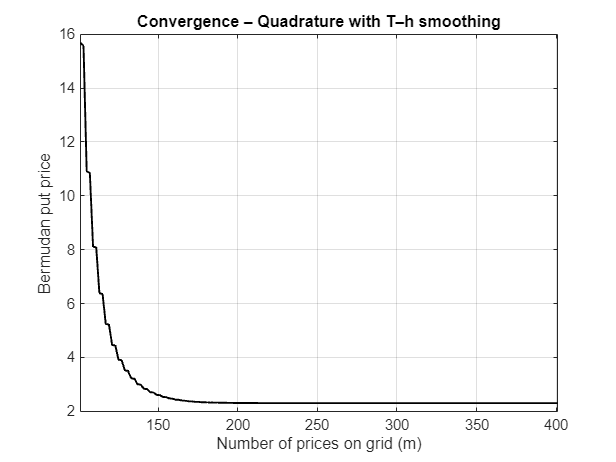

% ===== Convergence sweep =====
m_list = 101:2:m_grid;
prices = nan(size(m_list));
for k = 1:numel(m_list)
    prices(k) = bermudan_quad_smooth(S0,K,r,q,sigma,T,n_steps,m_list(k));
end

% ===== Plot =====
figure; hold on; box on;
plot(m_list, prices,'k-','LineWidth',1.3);
xlabel('Number of prices on grid (m)');
ylabel('Bermudan put price');
title('Convergence – Quadrature with T–h smoothing');
grid on; xlim([min(m_list) max(m_list)]);

toc;

Elapsed time is 0.861441 seconds.


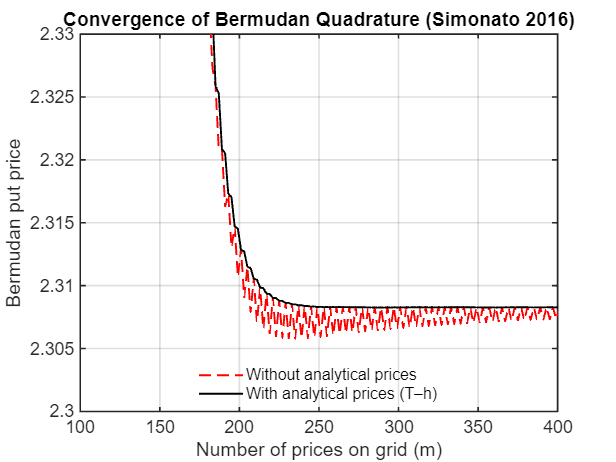

%% Combined Convergence Plot for Naive vs T–h smoothing
clear; clc; tic;

S0=50; K=50; r=0.05; q=0.02; sigma=0.30;
T=60/365; n_steps=60; m_grid=401;
m_list = 101:2:m_grid;

prices_naive  = nan(size(m_list));
prices_smooth = nan(size(m_list));

for k = 1:numel(m_list)
    prices_naive(k)  = bermudan_quad_naive(S0,K,r,q,sigma,T,n_steps,m_list(k));
    prices_smooth(k) = bermudan_quad_smooth(S0,K,r,q,sigma,T,n_steps,m_list(k));
end

% ===== Plot comparison =====
figure; hold on; box on;
plot(m_list, prices_naive, 'r--','LineWidth',1.3);
plot(m_list, prices_smooth,'k-','LineWidth',1.3);
legend('Without analytical prices','With analytical prices (T–h)');
xlabel('Number of prices on grid (m)');
ylabel('Bermudan put price');
title('Convergence of Bermudan Quadrature (Simonato 2016)');
grid on;
xlim([100 400]);
ylim([2.300 2.330]);
yticks(2.300:0.005:2.330);
set(gca,'FontSize',12,'LineWidth',1.1);
legend('Location','best','Box','off');

toc;

Elapsed time is 1.598569 seconds.
